# Frivillig opgave -- Mathias Bruun Hooumøller - 202006837

# Opgave 1

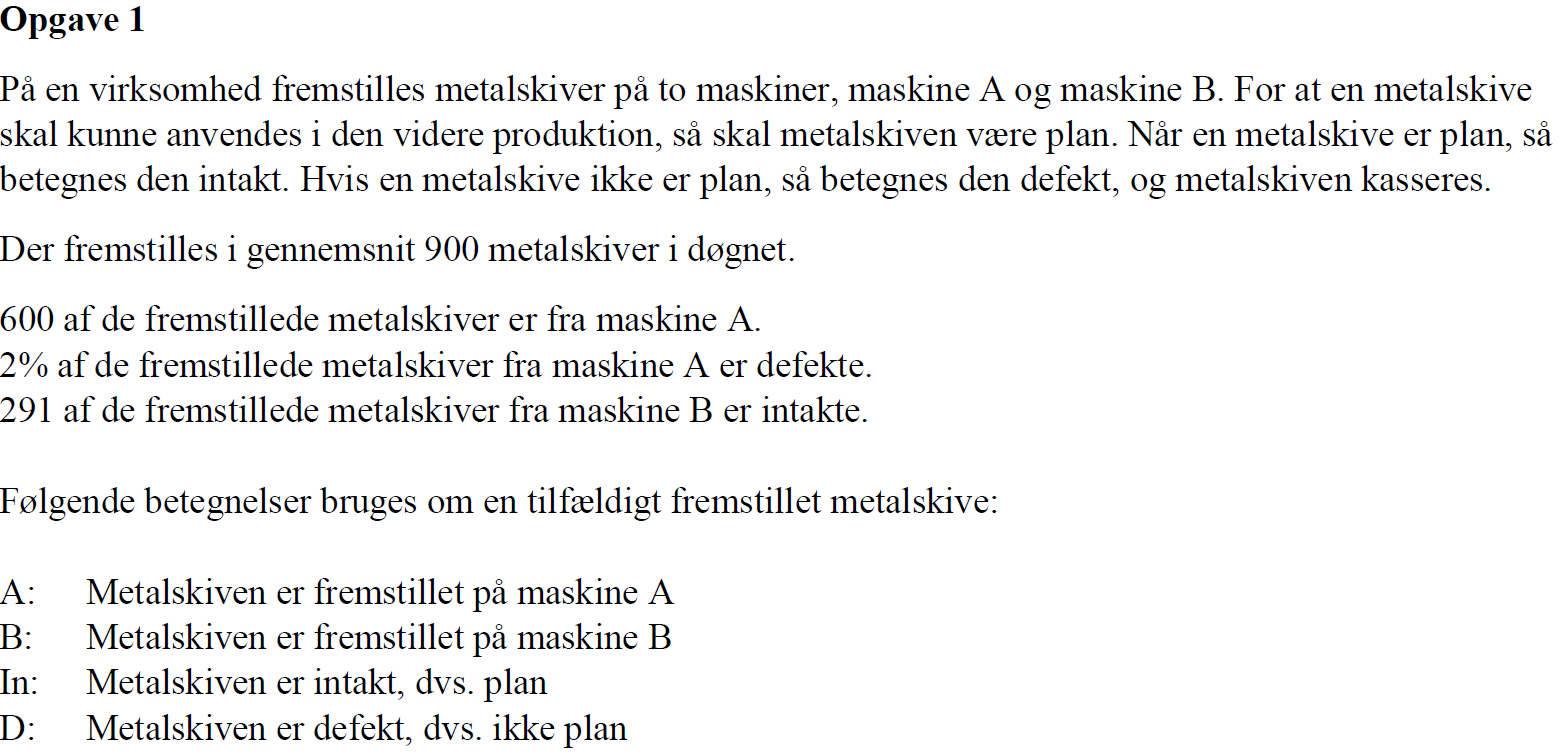

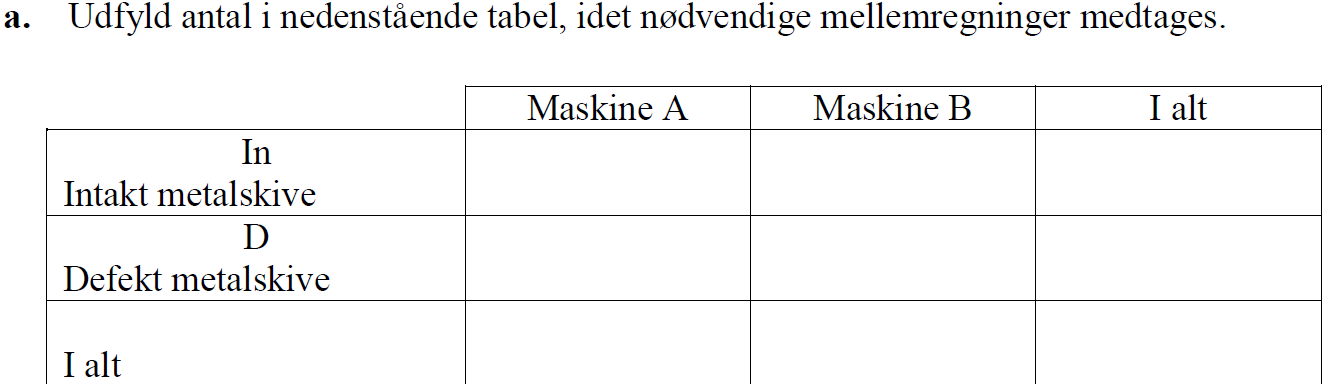

total = 900;
A_tot = 600;
A_D = A_tot * 0.02

A_D = 12

A_In = A_tot - A_D 

A_In = 588

B_tot = total - A_tot

B_tot = 300

B_In = 291

B_In = 291

B_D = B_tot - B_In

B_D = 9

A_tab = [A_In, A_D, A_tot];
B_tab = [B_In, B_D, B_tot];
tot_tab = [A_In + B_In, A_D + B_D, total];
T = table(A_tab', B_tab', tot_tab',VariableNames={'Maskin A', 'Maskin B', 'I alt'}, RowNames={'In', 'D', 'I alt'})

T = 3×3 table
             Maskin A    Maskin B    I alt
             ________    ________    _____

    In         588         291        879 
    D           12           9         21 
    I alt      600         300        900 


En tilfældig blandt de fremstillede metalskiver udtages.

### b)

Beregn sandsynlighederne for følgende:

Metalskiven er fremstillet på maskine A, P(A)

Metalskiven er fremstillet på maskine B, P(B)

Metalskiven er fremstillet på maskine A og er intakt, P(A∩In)

Metalskiven er fremstillet på maskine B og er intakt, P(B∩In)

P_A = A_tot / total

P_A = 0.6667

P_B = B_tot / total

P_B = 0.3333

P_A_og_In = A_In / total

P_A_og_In = 0.6533

P_B_og_In = B_In / total

P_B_og_In = 0.3233

### c)

Beregn sandsynlighederne for følgende:

Metalskiven er intakt, P(In)

Metalskiven er defekt, P(D)

Metalskiven er intakt, når den er fremstillet på maskine B, P(In|B)

Metalskiven er defekt, når den er fremstillet på maskine B, P(D|B)

P_In = (A_In + B_In) / total

P_In = 0.9767

P_D = (A_D + B_D) / total

P_D = 0.0233

P_In_in_B = B_In/B_tot

P_In_in_B = 0.9700

P_D_in_B = B_D/B_tot % eller 1 - P_In_in_B

P_D_in_B = 0.0300

### d)

Er der uafhængighed mellem hændelsen: metalskiven er intakt, og hændelsen metalskiven er fremstillet på maskine B. Svaret skal begrundes.

Vi benytter reglen for uafhængihed ved at sammenligne om sandsynligheden for at få en intakte indeholdt i B er lig med at trække en intakte i det totale.

P_In_in_B == P_In

ans = logical
   0


Dette er ikke opfyldt og hændelserne er derfor **ikke afhængige.**

# Opgave 2

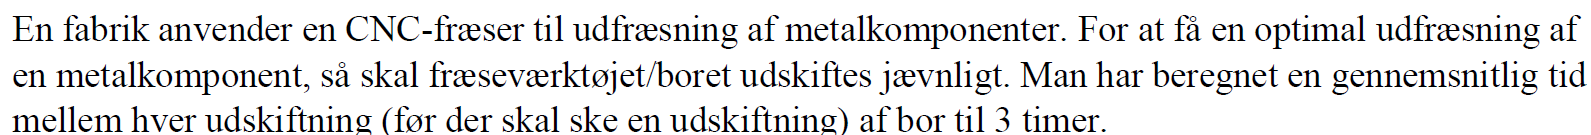

### a)

Hvilken sandsynlighedsfordeling er hensigtsmæssig at anvende til beskrivelse af tiden mellem udskiftning af bor?

Opskriv det generelle udtryk for denne fordelings sandsynlighedsfunktion (tæthedsfunktion).

En kontinuert normal fordeling vil være bedst

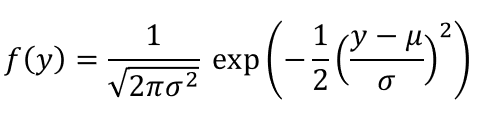

### b)

Bestem det gennemsnitlige antal udskiftning af bor pr. time.

Dette er 1/3 da der skiftes hver 3. time.

### c)

Bestem fordelingens middelværdi, varians og standardafvigelse

Middel værdien er 3 timer

standardafvigelse($\sigma$) = 1 time

Varians 1 time lig $\sigma^2$

Således har vi middelværdien bor skift til

### d)

Bestem sandsynligheden for at boret skal udskiftes, inden for de første 2 timers brug.

p_2 = normcdf(2,3)

p_2 = 0.1587

Sandsynligheden er således den kumulerede sandsynlighed op til 2 timer som er 15,9%

### e)

Bestem sandsynligheden for at der går mere end 6 timer før boret skal udskiftes.

p_6op = 1 - normcdf(6,3)

p_6op = 0.0013

Her er sandsynligheden kun 0,13% da vi er lige ved 3 $\sigma$.

### f)

Bestem sandsynligheden for at der går mellem 2 og 4 timer før boret skal udskiftes.

p_2til4 = normcdf(4,3) - normcdf(2,3)

p_2til4 = 0.6827

Der er 68,3% sandsynlighed for at det skal skiftes her.

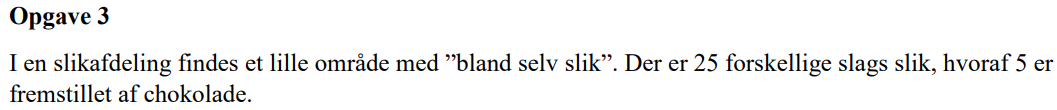

### a)

Hvad er sandsynligheden for et stykke chokolade-slik, hvis man tager et tilfældigt stykke slik?

choko = 5/ 25

choko =    0.200000000000000


En slikpose udgør 15 forskellige slags slik.

### b)

Opskriv udtrykket for sandsynligheden for, at få netop 4 stykker chokolade-slik i en slikpose og bestem denne sandsynlighed.

hvor 

p er sandsynligheden = 0,2

n er antal træk = 15

y er antal chokolader = 4

format long
binopdf(4,15,choko)

ans =    0.187604171489280


### c)

Hvor mange forskellige slikposer kan man blande?